Bewegung der MHT Einheit

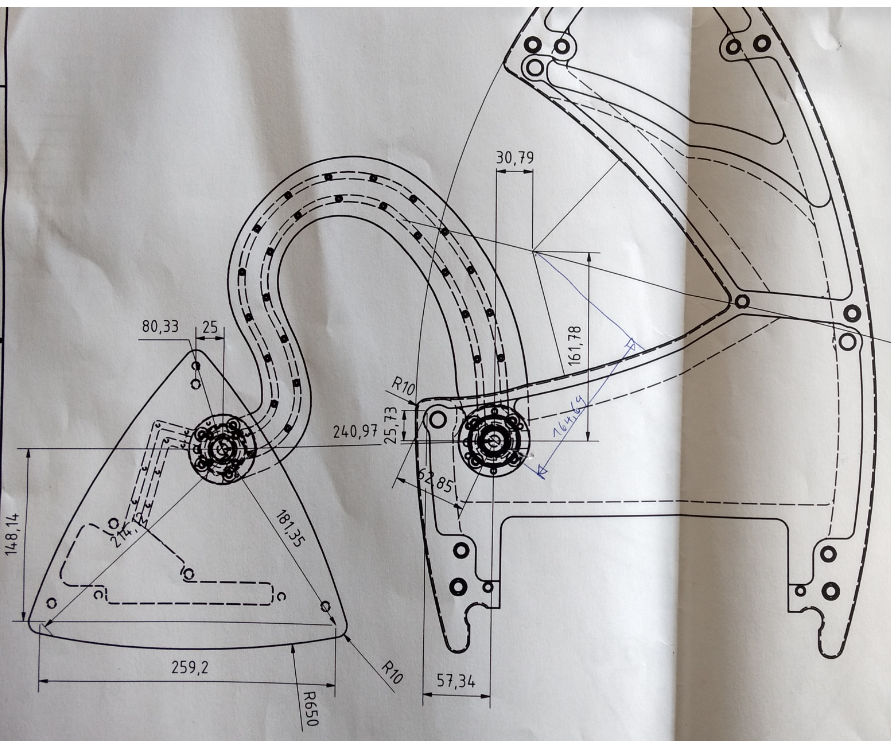

Definiton der Geometrie

     global  colldata;
    
    RAD = pi/180;
    rd= 650;     % Aussenradius
    l_spalt=3; % Spaltmass
    r_eck = 10; % Eckradius
    rdB= rd+l_spalt;   % Radius Innenbögen
    rd1= rd-r_eck;  % Radius Eckpunkte
    ld = 259.2;  % Basisbreit MHT
    xPb = 235.67; %XKoordinate der Pilotbox in Nullstellung
    yPb = 50.25; % Y Koordinate der Pilotbox in Nullstellung
    
    %  kx=22;      % Krorrekturlänge
     kx= 17.21; % Krorrekturlänge neu
    lhx0=81.8;   % Länge Bogen bis gesetzter Punkt
    hd = ld*sqrt(3)/2;   % höhe MHT Dreieck
    hm= ld/(2*sqrt(3));  % Mittelpunktslage MHT
    pd = asin((ld+r_eck)/(2*rd1)); % Bogenwinkel MHT
    rd2= sqrt(rd1*rd1-(ld/2)*(ld/2)); % Höhe über Sekante bis Mittelpunkt
    hr= rd2-hm; % Höhe Mittelpunkt Aussenradius
    pr= -pd:0.01:pd; % Bogen für MHT
    oy= 25.0;      % Lage x Drehpunkt MHT
    ox= hm-148.14; % Lage y Drehpunkt MHT
    lmb = -161.78  - kx*sin(-16.52*RAD);  % Abstand x MHT, Bass
    lmb = -163.18  - kx*sin(-16.52*RAD);  % Abstand x MHT, Bass
    lmh = +30.79  + kx*cos(-16.52*RAD);  % Abstand y MHT, Bass
    PoB =  [ lmb, lmh]; % Mittelpunkt Box in Nullstellung
    alfa0=-asin(lmb/(hr));  % Drehung MHD in Nullstellung
    %alfa1= alfa0+120*RAD;
    alfa1= alfa0;
    
   
    mBox.thetaMin=[ -5*RAD,  -140*RAD];
    mBox.thetaMax=[100*RAD,    30*RAD];
    mBox.rd=rd;
    mBox.pd=pd;
    mBox.r_eck=r_eck;
    mBox.l_spalt= l_spalt;
    mBox.alfa0=alfa0;
    mBox.alfa1 = alfa1;
    mBox.PoB =  PoB;
    mBox.Po=[ox, oy];
    mBox.P0=[0, 0]+PoB;
    mBox.P1=[-hd+hm, 0];
    mBox.P2=[hm,-ld/2,];
    mBox.P3=[hm, ld/2,];
    mBox.M1=[ -hr, 0];
    mBox.M2=[ hr/2, -hr*sqrt(3)/2];
    mBox.M3=[ hr/2,  hr*sqrt(3)/2];
    mBox.Po= rot(mBox.Po, alfa1)+PoB;
    mBox.P1= rot(mBox.P1, alfa1)+PoB;
    mBox.P2= rot(mBox.P2, alfa1)+PoB;
    mBox.P3= rot(mBox.P3, alfa1)+PoB;
    mBox.M1= rot(mBox.M1, alfa1)+PoB;
    mBox.M2= rot(mBox.M2, alfa1)+PoB;
    mBox.M3= rot(mBox.M3, alfa1)+PoB;
    pr=pr+alfa1;
    mBox.pr=pr;
    bb=400; % breite der BassBox  
    mBox.M4a=[-25.72,rd-57.34-r_eck]; % Mittelpunkt für Ausenkreis
    % lhr= hr*(1.0-cos(alfa0));
    ym=  bb/2-57.34-r_eck  % Mittelline der Box

ym = 132.6600

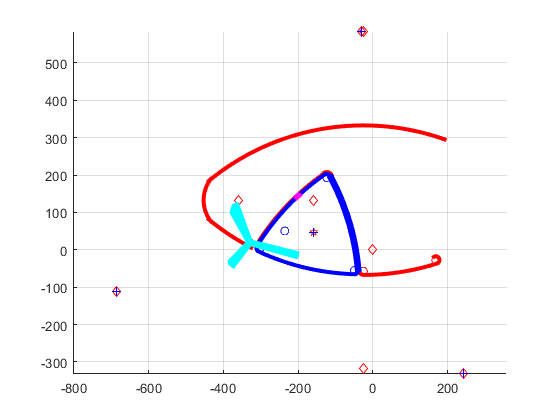

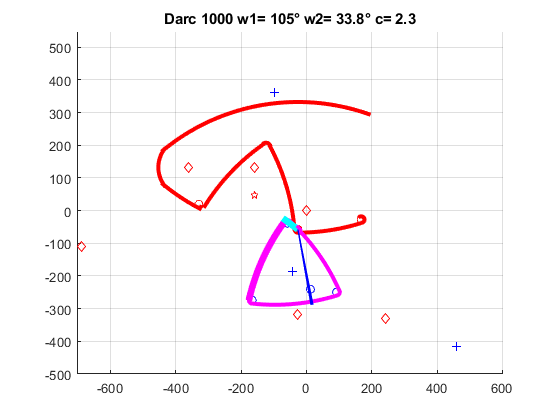

    mBox.M5=[-360,ym];   % Mittelpunkt hinterer Boxabschluss
    mBox.M0=[0, ym];   % Box Center
    mBox.M4b =  [-25.72, -rd+bb - (57.34+r_eck)];

      % Definition der Kreisbögen
     mBox.k1.m= mBox.M1;
     mBox.k1.r= rd;
     mBox.k1.p= pr-0*RAD;
     mBox.k1.b=true;

     mBox.k2.m= mBox.M2;
     mBox.k2.r= rd;
     mBox.k2.p= pr+120*RAD;
     mBox.k2.b=true;

     mBox.k3.m= mBox.M3;
     mBox.k3.r= rd;
     mBox.k3.p= pr-120*RAD;
     mBox.k3.b=true;

     mBox.kx1.m= mBox.M1;
     mBox.kx1.r= rdB;
     mBox.kx1.p= pr-0*RAD;
     mBox.kx1.b=false;

     mBox.kx2.m= mBox.M2;
     mBox.kx2.r= rdB;
     mBox.kx2.p= pr+120*RAD;
     mBox.kx2.b=false;

     mBox.kx3.m= mBox.M3;
     mBox.kx3.r= rdB;
     mBox.kx3.p= pr-120*RAD;
     mBox.kx3.b=false;
     
     mBox.kx4.m=mBox.M4a;
     mBox.kx4.r= rd;
     mBox.kx4.p= -(72:1:90)*RAD; % Bogen Ausenkreis
     mBox.kx4.b=true;

     mBox.kx5.m=mBox.M4a;
     mBox.kx5.r= rd;
     mBox.kx5.p= -(117:1:130)*RAD; % Bogen Ausenkreis
     mBox.kx5.b=true;
     
     % Bogen Mittelpunkte für feststehende Bassbox
     mBox.MB1=mBox.M1;
     mBox.MB2=mBox.M2;
     mBox.MB3=mBox.M3;
     mBox.PB3=mBox.P3;
  
 
  
    mBox.Po1= [-25.73,  -57.34];
    mBox.Po0= rotX(mBox.M4a, mBox.Po1, 200/rd);
    mBox.Po2 = rotX(mBox.M4a, mBox.Po1, -(2*mBox.pd+(4*r_eck+2*l_spalt)/rd));
    mBox.M5=[-360,ym];   % Mittelpunkt hinterer Boxabschluss
    mBox.M0=[lmb,ym]; % Box Center
    mBox.plot=3;
  
    
        
    %% Durchführen der Simulation
    % Anlegen der Grafik und der Videaufzeichnung
    
 %  vw = VideoWriter('Animation_Kollission_6.avi'); 
 %  open(vw);

    fig4 =  figure(4);
    axis equal
    grid on
    hold on
    
    plotBassBox(mBox);
    rBox= rotateBox(mBox, 0, 0);
    Plot_Box(rBox,0);
        
    % Definition des Definitionsbereiches der Schwenkwinkel
    
    step=0.2;
  %   theta1= (-5:step:115 )*RAD ;
  %   theta2= (-135:step:55)*RAD;
     theta1=   (  -5:step:105)*RAD;
     theta2=   (-145:step:35)*RAD;
     
    % theta1=   -5*RAD+ x*0.3+(  -3:step:3)*RAD;
    % theta2=   -145*RAD+t*0.3;
     
  %   theta1=   (  89:step/2:90)*RAD;
  %   theta2=   (-80:(step/2):-70)*RAD;

       nx=length(theta1);
       ny=length(theta2);
      flt= ones(nx,ny);
      colldata = zeros(nx,ny,40);
      tic
      %  Simulation in 2 Schleifen
     for w1=1:nx
          for w2=1:ny

  
    if mod(w2,10)==0
    
    end
       
    rBox= rotateBox(mBox, theta1(w1), theta2(w2));
  
  
    rBox.wi1= w1; 
    rBox.wi2= w2;
    rBox.theta=[theta1(w1),theta2(w2)];
  %    plotBassBox(mBox);
  %  Plot_Box(rBox,0);
    kol=checkCollision(rBox);
        if mod(5*w1+w2,50)==0
              clf;
     axis equal
     grid on
     hold on
    xlim([-700 600])
    ylim([-500 550])
            plotBassBox(mBox);
            title(['Darc 1000 w1= ',num2str(theta1(w1)/RAD), '° w2= ', num2str(theta2(w2)/RAD ),'° c= ',num2str(kol) ])
           
             Plot_Box(rBox,kol);
            drawnow
     end
  
  %  frame = getframe (fig4);
  %   writeVideo (vw, frame);  
     flt(w1, w2)=kol;
          end
     end

     elapsedTime = toc

elapsedTime = 2.8551e+03

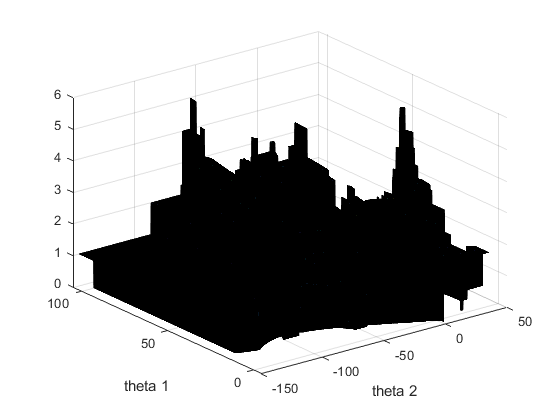

%     close(vw);
     
     figure(5);
     [X,Y]=meshgrid(theta2/RAD,theta1/RAD);
      surf(X,Y,flt);
      xlabel('theta 2');
      ylabel('theta 1');

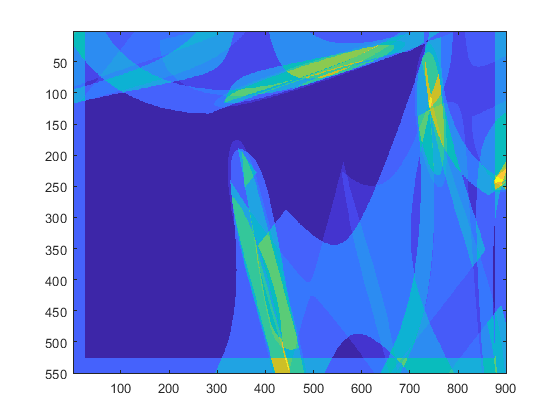

       figure(6);
       imagesc(flt)      

  %  [Li, Lj]= runLenghtEncoding(flt',0.3)
    l=norm(mBox.PoB-mBox.Po)

l = 77.4606

  %  axis equal
  %  grid on
  %  plotBassBox(mBox);
  %  hold off
  %  mBox
  save('flt_3_26.mat', 'flt', 'theta1', 'theta2','mBox', 'step' ,'colldata')

`% byteArray[0] = (byte)((value >> 12) & 0x0F) ;`

`% byteArray[1] = (byte)((value >> 8) & 0x0F) ;`

`% byteArray[2] = (byte)((value >> 4) & 0X0F);`

`% byteArray[3] = (byte)((value & 0X0F));`

`case(b){`

`case 0x0: // alles frei`

`case 0x1:`

`case 0x2:`

`case 0x3:`

`case 0x04:`

`case 0x0f: // alles voll`

`}`

Collision check

 function  plotBassBox(box)
    RAD= pi/180;
    rd2=box.rd+box.l_spalt;
    prb = -box.pd:0.01:box.pd;
    prb=prb+box.alfa1;
    % Innen Bogen 1 vorn
    plot(box.MB1(1)+box.kx1.r*cos(box.kx1.p), box.MB1(2)+box.kx1.r*sin(box.kx1.p),'r','LineWidth',3);
    % Innen Bogen 2 hinten
    plot(box.MB2(1)+box.kx2.r*cos(box.kx2.p), box.MB2(2)+box.kx2.r*sin(box.kx2.p),'r','LineWidth',3);
    
    % kleiner Innenradius zwischen B1 und B2
    rp=15;
    pp=(-60:10:60)*RAD-box.alfa0;
    plot(box.PB3(1)+rp*cos(pp+90*RAD), box.PB3(2)+rp*sin(pp+90*RAD),'r','LineWidth',3);

    rb=93;   % Radius Boxabschluss
    ps=(70:1:130)*RAD; % Bogen Ausenkreis
    ym= box.M0(2);
    plot([0, box.M0(1),box.kx1.m(1),box.kx2.m(1), box.kx3.m(1), box.M4a(1),box.M4b(1),box.M5(1)],...
         [0, box.M0(2),box.kx1.m(2),box.kx2.m(2), box.kx3.m(2), box.M4a(2),box.M4b(2),box.M5(2)], 'rd')
   
    % Box aussen oben
    plot(box.M4b(1)+box.rd*cos(ps), box.M4b(2)+box.rd*sin(ps),'r','LineWidth',3);
    
    % Box aussen unten
    plot(box.kx4.m(1)+box.kx4.r*cos(box.kx4.p), box.kx4.m(2)+box.kx4.r*sin(box.kx4.p),'r','LineWidth',3);
    plot(box.kx5.m(1)+box.kx5.r*cos(box.kx5.p), box.kx5.m(2)+box.kx5.r*sin(box.kx5.p),'r','LineWidth',3);
    
    
     % Box Abschluss
     pa=(140:1:220)*RAD;
    plot(box.M5(1)+rb*cos(pa), box.M5(2)+rb*sin(pa),'r','LineWidth',3);

    % Drehpunkt  
    plot([ box.PoB(1)],[ box.PoB(2)], 'rp');
    
    % Rundungen an der Bassbox
    plot([ box.Po0(1),box.Po1(1),  box.Po2(1)],[ box.Po0(2),box.Po1(2),  box.Po2(2)], 'ro');
    rp=10;
    plot(box.Po1(1)+rp*cos(pp-110*RAD), box.Po1(2)+rp*sin(pp-110*RAD),'r','LineWidth',3);
    plot(box.Po2(1)+rp*cos(pp-60*RAD),  box.Po2(2)+rp*sin(pp-60*RAD),'r','LineWidth',3);
    plot(box.Po0(1)+rp*cos(2*pp+60*RAD),  box.Po0(2)+rp*sin(2*pp+60*RAD),'r','LineWidth',3);
 end
 
 

Plotet Bass Box

Drehung für MHT

 function rbox = rotateBox(box, phi1, phi2)
  rbox=box;
  o=[0,0];
  box.Po=rotX(o,box.Po, phi1);
  box.P0=rotX(o,box.P0, phi1);
  box.P1=rotX(o,box.P1, phi1);
  box.P2=rotX(o,box.P2, phi1);
  box.P3=rotX(o,box.P3, phi1);
  box.M1=rotX(o,box.M1, phi1);
  box.M2=rotX(o,box.M2, phi1);
  box.M3=rotX(o,box.M3, phi1);
  
  rbox.Po=rotX(box.Po, box.Po, phi2);
  rbox.P0=rotX(box.Po, box.P0, phi2);
  rbox.P1=rotX(box.Po, box.P1, phi2);
  rbox.P2=rotX(box.Po, box.P2, phi2);
  rbox.P3=rotX(box.Po, box.P3, phi2);
  rbox.M1=rotX(box.Po, box.M1, phi2);
  rbox.M2=rotX(box.Po, box.M2, phi2);
  rbox.M3=rotX(box.Po, box.M3, phi2);
  rbox.pr= box.pr+phi1+phi2;
  rbox.phi1=phi1;
  rbox.phi2=phi2;
  
  rbox.k1.m= rbox.M1;  
  rbox.k2.m= rbox.M2;  
  rbox.k3.m= rbox.M3;
  rbox.k1.p= box.k1.p+phi1+phi2;
  rbox.k2.p= box.k2.p+phi1+phi2;
  rbox.k3.p= box.k3.p+phi1+phi2;
  end
  
  

Plotet MHT

  function Plot_Box(box, kol)
  RAD = pi/180;
    hold on
    plot([box.Po(1), box.P1(1), box.P2(1), box.P3(1) ],...
         [box.Po(2), box.P1(2), box.P2(2), box.P3(2) ],'bo');
    plot([box.P0(1), box.M1(1), box.M2(1), box.M3(1) ],...
         [box.P0(2), box.M1(2), box.M2(2), box.M3(2) ],'b+');
    rd=box.rd;
    pr=box.pr;
    col= 'b';
    if kol > 0 col = 'c';
    end
    if kol >= 1 col = 'm';      
    end
    plot(box.k1.m(1)+box.k1.r*cos(box.k1.p), box.M1(2)+box.k1.r*sin(box.k1.p),col,'LineWidth',5);
    plot(box.k2.m(1)+box.k2.r*cos(box.k2.p), box.M2(2)+box.k2.r*sin(box.k2.p),col,'LineWidth',3);
    plot(box.k3.m(1)+box.k3.r*cos(box.k3.p), box.M3(2)+box.k3.r*sin(box.k3.p),col,'LineWidth',3);

    rp=10;
    pp=(-60:10:60)*RAD+(-box.alfa0+box.phi1+box.phi2);
    plot(box.P1(1)+rp*cos(pp+(90+120)*RAD), box.P1(2)+rp*sin(pp+(90+120)*RAD),col,'LineWidth',3);
    plot(box.P2(1)+rp*cos(pp+(90-120)*RAD), box.P2(2)+rp*sin(pp+(90-120)*RAD),col,'LineWidth',3);
    plot(box.P3(1)+rp*cos(pp+(90)*RAD),     box.P3(2)+rp*sin(pp+(90)*RAD),col,'LineWidth',3);
    
    end
   

Plotten der MHT-Box und berechnen der gedrehten koordinaten

%      function xbox =plotBox(box, phi1, phi2)
%      
%      xbox=box;
%      xbox.kx1.r = box.k1.r-0.03;
%      xbox.kx2.r = box.k2.r-0.03;
%      xbox.kx3.r = box.k3.r-0.03;
%      r4= 0.3;
%      
%      phi12=phi1+phi2;
%    
%      xbox.phi12=phi12; 
%      
%      [xm, ym] = rotP(box.x2,box.y2,phi1);
%   
%     
%       [x11, y11] = rotP(box.k1.m(1)-box.x2,box.k1.m(2)-box.y2,phi2);
%       [x12, y12] = rotP(box.k2.m(1)-box.x2,box.k2.m(2)-box.y2,phi2);
%       [x13, y13] = rotP(box.k3.m(1)-box.x2,box.k3.m(2)-box.y2,phi2);
%        
%       [x1, y1] = rotP(x11,y11,phi1);
%       [x2, y2] = rotP(x12,y12,phi1);
%       [x3, y3] = rotP(x13,y13,phi1);
%        xbox.kx1=  xbox.k1;
%        xbox.kx1=  xbox.k1;
%        xbox.kx1=  xbox.k1;
%        
%       xbox.kx1.p = box.k1.p+phi12;
%       xbox.kx2.p = box.k2.p+phi12;
%       xbox.kx3.p = box.k3.p+phi12;
%      
%       xbox.kx1.m=[x1+xm,y1+ym];
%       xbox.kx2.m=[x2+xm,y2+ym];
%       xbox.kx3.m=[x3+xm,y3+ym];
%       
%       xbox.P2= [xbox.kx1.m(1)+xbox.kx1.r*cosd(min(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(min(xbox.kx1.p))];
%       xbox.P3= [xbox.kx1.m(1)+xbox.kx1.r*cosd(max(xbox.kx1.p)),xbox.kx1.m(2)+xbox.kx1.r*sind(max(xbox.kx1.p))];
%       P=(xbox.P2+xbox.P3)/2;
%       R=[-(xbox.P3(2)-xbox.P2(2)),(xbox.P3(1)-xbox.P2(1))]/norm(xbox.P3-xbox.P2);
%       xbox.P4= [P(1) + r4*R(1),P(2)+r4*R(2)];
%       
% 
%       if box.plot >1 
%     
%       plot(xbox.kx1.m(1)+xbox.kx1.r*cosd(xbox.kx1.p),xbox.kx1.m(2)+xbox.kx1.r*sind(xbox.kx1.p), 'b');
%       plot(xbox.kx2.m(1)+xbox.kx2.r*cosd(xbox.kx2.p),xbox.kx2.m(2)+xbox.kx2.r*sind(xbox.kx2.p), 'b');
%       plot(xbox.kx3.m(1)+xbox.kx3.r*cosd(xbox.kx3.p),xbox.kx3.m(2)+xbox.kx3.r*sind(xbox.kx3.p), 'b');
%       plot([xbox.kx1.m(1),xbox.kx2.m(1),xbox.kx3.m(1)],[xbox.kx1.m(2),xbox.kx2.m(2),xbox.kx3.m(2)], 'b+')
%     
%      
%       
%     
%       plot([P(1)],[P(2) ], 'gp');
%       plot([xbox.P2(1) xbox.P3(1) xbox.P4(1) ],[xbox.P2(2) xbox.P3(2), xbox.P4(2)], 'bp');
%       plot([ xm ],[ ym], 'bo');
%       end
%       
%     end
%     

Prüfen auf Kollision

  %************************************   
   
   function nk= checkCollision(box)
    nk=0;
    
    nk = nk+ checkLimit(box);
   
    nk = nk+ checkPointCircle(box, box.Po0, box.k1,false,1); % Eckpunkt Bassbox Front MHT
    nk = nk+ checkPointCircle(box, box.Po0, box.k2,false,2); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box, box.Po0, box.k3,false,3); % Eckpunkt Bassbox Links MHT    
 
    nk = nk+ checkPointCircle(box, box.Po1, box.k1,false,4); % Eckpunkt Bassbox Front MHT
    nk = nk+ checkPointCircle(box, box.Po1, box.k2,false,5); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box, box.Po1, box.k3,false,6); % Eckpunkt Bassbox Links MHT    

    nk = nk+ checkPointCircle(box, box.Po2, box.k1,false,7); % Eckpunkt Bassbox Front MHT
    nk = nk+ checkPointCircle(box, box.Po2, box.k2,false,8); % Eckpunkt Bassbox Rechts MHT
    nk = nk+ checkPointCircle(box, box.Po2, box.k3,false,9); % Eckpunkt Bassbox Links MHT    

    nk = nk+ checkPointCircle(box, box.P2, box.kx1,true,10); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P2, box.kx2,true,11); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P2, box.kx4,false,12); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P2, box.kx5,false,13); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box, box.P3, box.kx1,true,14); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P3, box.kx2,true,15); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P3, box.kx4,false,16); % rechte Ecke MHT Buch Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P3, box.kx5,false,17); % rechte Ecke MHT Buch Vorn Bassbox

    nk = nk+ checkPointCircle(box, box.P1, box.kx1,true,18); % hintere Ecke MHT Bucht Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P1, box.kx2,true,19); % hintere Ecke MHT Bucht hinten Bassbox
    nk = nk+ checkPointCircle(box, box.P1, box.kx4,false,20); % hintere Ecke MHT Aussen Vorn Bassbox
    nk = nk+ checkPointCircle(box, box.P1, box.kx5,false,21); % hintere Ecke MHT hinter Vorn Bassbox

    nk = nk+ checkPoints(box, box.P1,box.Po1,30);
    nk = nk+ checkPoints(box, box.P2,box.Po1,31);
    nk = nk+ checkPoints(box, box.P3,box.Po1,32);
    nk = nk+ checkPoints(box, box.P1,box.Po2,33);
    nk = nk+ checkPoints(box, box.P2,box.Po2,34);
    nk = nk+ checkPoints(box, box.P3,box.Po2,35);
    nk = nk+ checkPoints(box, box.P1,box.Po0,36);
    nk = nk+ checkPoints(box, box.P2,box.Po0,37);
    nk = nk+ checkPoints(box, box.P3,box.Po0,38);
  
   end
   
   %************************************   
     function nk= checkLimit(box)
     nk=0;
     dmax = box.theta - box.thetaMax;
     dmin = box.theta - box.thetaMin;
     dmn=dmax>0;
     if sum(dmax>0) 
        colldata(box.wi1, box.wi2,39)= 2*dmn(1) + dmn(2); % Schwenkwinkel grenze
         nk=1; 
     end
     dmn=dmin<0;
     if sum(dmin<0) 
         colldata(box.wi1, box.wi2,40)= 2*dmn(1) + dmn(2); % Schwenkwinkel grenze
         nk=1; 
     end
     end
       %************************************   
    
      function nk= checkPoints(box, P1,P2, num)
   % prüfe ecke 
   nk=0;
    l_spalt=box.l_spalt;
    r_eck=box.r_eck;
    l= norm(P1 - P2);
    col='y'; lw=1;
    if l<(2*r_eck+l_spalt)
        colldata(box.wi1, box.wi2,num)= l-2*r_eck; % nahe dran
         col='c'; lw=3;
         nk=0.3;
    if(l<2*r_eck)
        colldata(box.wi1, box.wi2,num)= l-2*r_eck; % Kollision
        col='m'; lw=5;
        nk=1;
    end
    end

    if false % box.plot > 2
     plot([P1(1)  P2(1)],[P1(2)  P2(2)],col,'LineWidth',lw);
    end
    end
   %************************************   
   
  
    %************************************************
    % prüft Punkt und Kreisbogenauf Kollision
    function [nk, ret] = checkPointCircle(box, P, cir,flag,num)
    global colldata;
    RAD=pi/180;
    l_spalt=box.l_spalt;
    r_eck=box.r_eck;
    nk=0; % keine Kollision
     % prüfe Ecke 1 Mht auf bogen 1
    l=norm(P - cir.m);
   
    % prüfe ob auch Winkel stimmt 
    dx = P - cir.m;
    dxn= dx/norm(dx); % normierter Richtungsvektor
    a= atan2(dx(2), dx(1));
    if a<0 
        a=a+360*RAD ;
    end
    
    mi= min(cir.p);
    ma= max(cir.p);
   if mi<0 
        mi=mi+360*RAD ;
   end
   if ma<0 
        ma=ma+360*RAD ;
   end
    col='y'; lw=1;
    if (a>=mi && a<=ma) % Ecke ist innerhalb Kreisbogen
          if flag 
             xl= l+r_eck;
        else
             xl= l-(r_eck);  
        end
        dl= xl-cir.r;
        switch(num)
            case {4, 5, 6, 30, 31,32} % Ecke 1
                ret= 4;
            case {10, 11, 14, 15 ,18,19}  %  Box innen
                ret= 3;
            case {1, 2, 3, 7, 8, 9, 12, 13, 16, 17 ,20, 21,33,34, 35, 36, 37, 38}  %  Box aussen
                ret =2;
            otherwise
                ret= 1;
        end
        if (num ==12 || num ==16 || num==20) && (abs(dl)<25)
            dl;
        end
      
        if ((xl > cir.r) && flag ) || ((xl < cir.r) && ~flag )
          if(abs(l-cir.r)>150)
               % nk=nk+0.05; % Mögliche Fehlinterprätation wenn Hinderniss
               % Hinter der Box
                col='b'; lw=1;
          else 
              if ((abs(l-cir.r)> r_eck) && ~flag) || ((abs(l-cir.r)> r_eck) && flag) 
                nk= nk+0.3;  % Keine Kollision aber Abstand kleiner als Spalt
                col='c'; lw=3;
                lw=5;
                colldata(box.wi1, box.wi2,num)=  xl; % Naher dran
              else
                nk= nk+1;
                col='m'; lw=5;
                colldata(box.wi1, box.wi2, num )= xl; %  Kollision
              end
          end
               plot([P(1)  P(1)-dxn(1)*dl],[P(2)  P(2)-dxn(2)*dl],col,'LineWidth', lw);

        end
    end
        if a<mi || a>ma % Auserhalb des Winkelfensters
          col= 'g';
        end
        if false % box.plot > 2
         plot([P(1)  cir.m(1)],[P(2)  cir.m(2)],col,'LineWidth', 1);
        end
    end

    

Rotation um Winkel phi

%************************************   
function [x, y] = rotP(xo,yo, phi)
  x = cos(phi)*xo - sin(phi)*yo;
  y = sin(phi)*xo + cos(phi)*yo;
end

%************************************ 

Rotation eines Punkte mit dem Winkel phi

function Pr = rot(P, phi)
  Pr= ( [ cos(phi), -sin(phi); sin(phi)  cos(phi)] * P')';
end

%************************************   

Rotation eines Punktes P um den Punkt X mit Winkel phi

function Pr = rotX(X,P, phi)
  Pr= ( [ cos(phi), -sin(phi); sin(phi)  cos(phi)] * (P-X)')'+X;
end
    

Prüft ob punkt im Feld

function b = inArea(mf, x,y)
% find index
in = ceil( x/10);
b1 = ( y> mf(in,2) && y<(mf(in,3)));
b2=    (y< mf(in,4) || y>(mf(in,5)));
b= b1 && (isnan(mf(in,4)) || b2) ;  
end

Quadtree

function [i1,i2] =calcIndex(w1,w2)
    min1= min(theta1); min2= min(theta2);
    max1= max(theta1); max2= max(theta2);
    lr1= max1-min1;
    lr2= max2-min2;
    x1= (w1-min1)/lr1; % Normierte Koordinate von 0 bis 1
    x2= (w2-min2)/lr1; % Normierte Koordinate von 0 bis 1
    [n1,n2]=size(flt);  % Indexfelt
    i1= w1*n1+1;
    i1= w2*n2+1;
end

Erzeugt eine Quadtree von Flt

function node=quad(flt,lev)
   maxLev=5;
   [nf1,nf2]=size(flt);  % Indexfelt
   i1=0; i2=0;
   k1=nf1/2; k2=nf2/2;
   n1=  sum(flt(i1:k1 ,i2:k1 )<0.3,'all')
   if n1>0 
       if lev >= maxLev
         node.q1 = 1;  
       else
       node.q1= quad(flt(i1:k1 ,i2:k1 ),lev+1) 
       end
   end
   n2=  sum(flt(k1:nf1,i2:k1 )<0.3,'all')
     if n2>0   
          if lev >= maxLev
         node.q2 = 1;  
       else
       node.q2= quad(flt(k1:nf1,i2:k1),lev+1) 
       end
   end
   n3=  sum(flt(i1:k1 ,k2:nf2)<0.3,'all')
     if n3>0   
          if lev >= maxLev
         node.q3 = 1;  
       else
        node.q3= quad(flt(i1:k1 ,k2:nf2),lev+1 )
         end
   end
   n4=  sum(flt(i1:nf1,k2:nf2)<0.3,'all')
     if n4>0    
         if lev >= maxLev
         node.q4 = 1;  
       else
        node.q4= quad(flt(i1:nf1,k2:nf2),lev+1 )
     end
   end
 end

 function runLenghtEncoding(flt)
    [nf1,nf2]=size(flt);  % Indexfeld
     for i1=1:nf1
           for i2=1:nf2
               flt(i1,i2)
           end
     end
 end